## Topic 4 Nonlinear oscillators

This liveScript accompanies class materials for Topic 4. These exercises use Matlab's Symbolic Toolbox. Please see [this resource](https://www.mathworks.com/help/symbolic/computational-mathematics-in-symbolic-math-toolbox.html) for an excellent introduction to this toolbox.

**Exercise 1: Van der Pol. **Write a script in MATLAB to numerical solve and plot initial condition solutions for *u = -0.2 ,0.2, 1.0 *Please see. p. 153-156 in[ Acheson (1997) ](https://books.google.com/books/about/From_Calculus_to_Chaos.html?id=o3Aq3Jt5-gEC)for more details on this system.

processing... ... ...


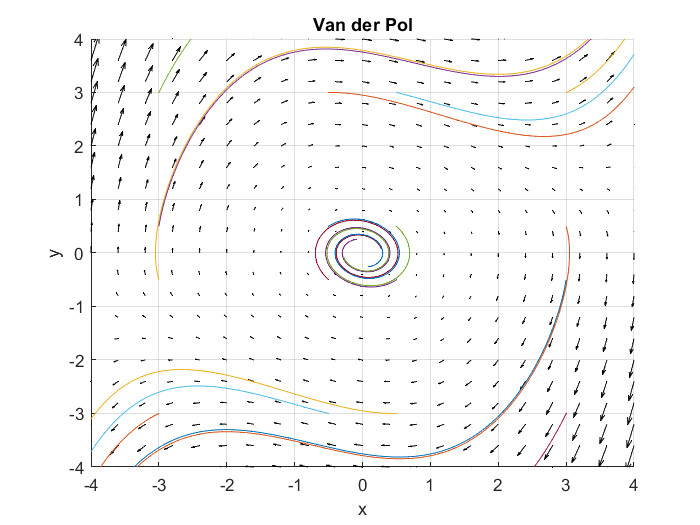

% The van der pol equation is implemented in the VanDerPol.m function. You
% may need to comment out "close all" on line 10 in that function. :)
% u = -0.2
figure
[t x] = VanDerPol([-3 -.5 .5 3],[-3 -.5 .5 3],-0.2,10);  % first set of numbers [-3 -.5 .5 3] are the initial for x (electric current) and the second set of numbers are the initial conditions for the y variable (velocity of current).

processing... ... ...


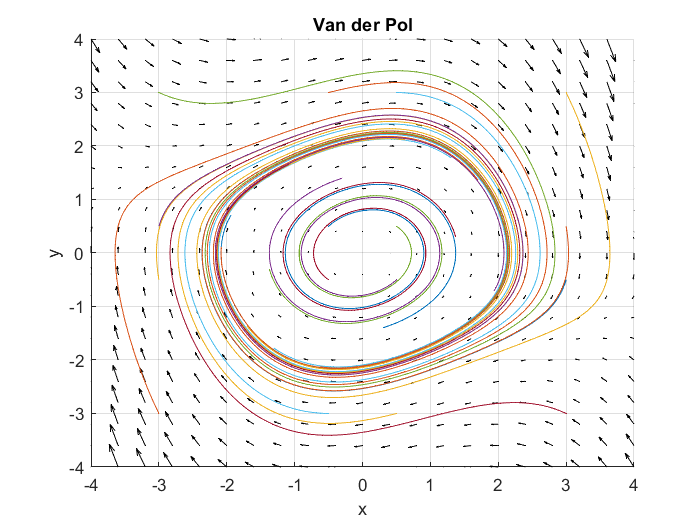

% u = 0.2
figure
[t x] = VanDerPol([-3 -.5 .5 3],[-3 -.5 .5 3],0.2,10);

processing... ... ...


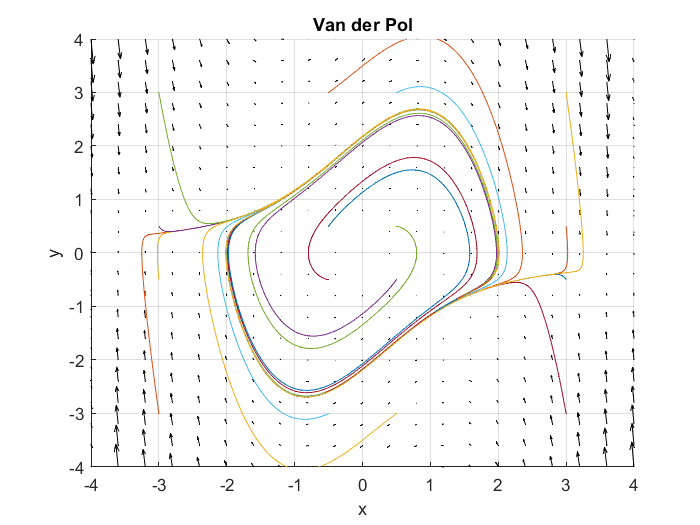

% u = 1
figure
[t x] = VanDerPol([-3 -.5 .5 3],[-3 -.5 .5 3],1,10);

**Exercise 2: Rayleigh. ** Recast the system in general form, and determine the fixed point(s). Write a script in MATLAB to numerical solve and plot initial condition solutions for *ε = -0.2 ,0.3, 1.0 *

% Convert the second-order differential equation to a system of first-order differential equations.
syms x(t) u 
eqn = diff(x,2)+u*(1-diff(x,1)^2)*diff(x,1)+x==0;
V = odeToVectorField(eqn)

$$V = \left(\begin{array}{c} Y_{2}\\ u\,\left({Y_{2}}^{2}-1\right)\,Y_{2}-Y_{1} \end{array}\right)$$

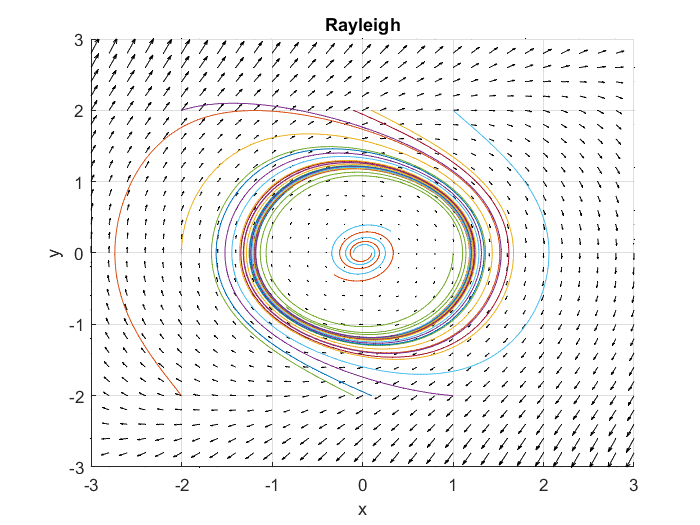


% Run the Rayleigh system using the Rayleigh.m function. You may need to
% comment out "close all" on line 9 for it to display correctly.
% u = -0.2
[t,x] = Rayleigh([-2 -.1 .1 1],[-2 0 2],-0.2,15); 

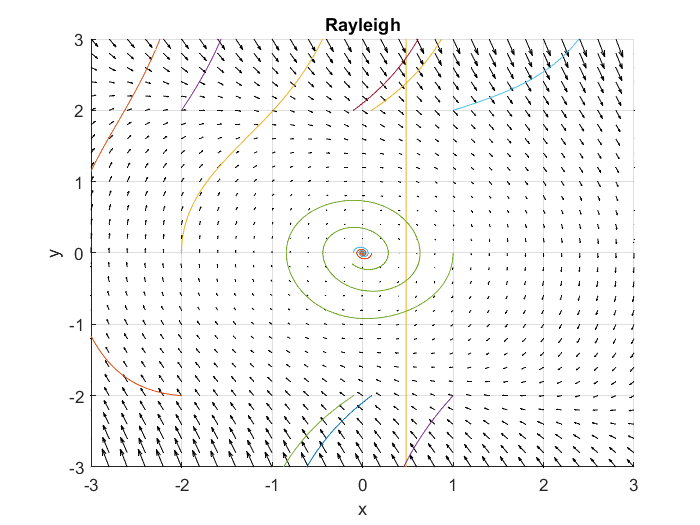


% u = 0.3
[t,x] = Rayleigh([-2 -.1 .1 1],[-2 0 2],0.3,15);

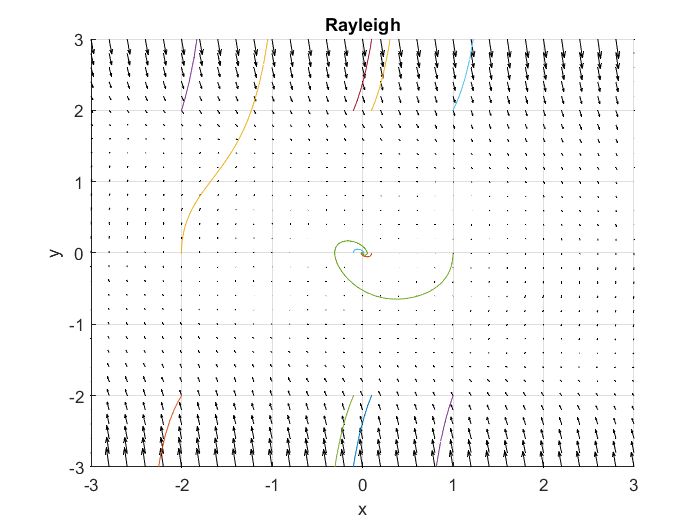


% u = 1
[t,x] = Rayleigh([-2 -.1 .1 1],[-2 0 2],1,15);

Simulate the generalized versions of Van Der Pol and Rayleigh systems described on slide 7 using animated functions. Again, on all these functions, you may need to comment out "close all" on line 9 for it to display correctly.

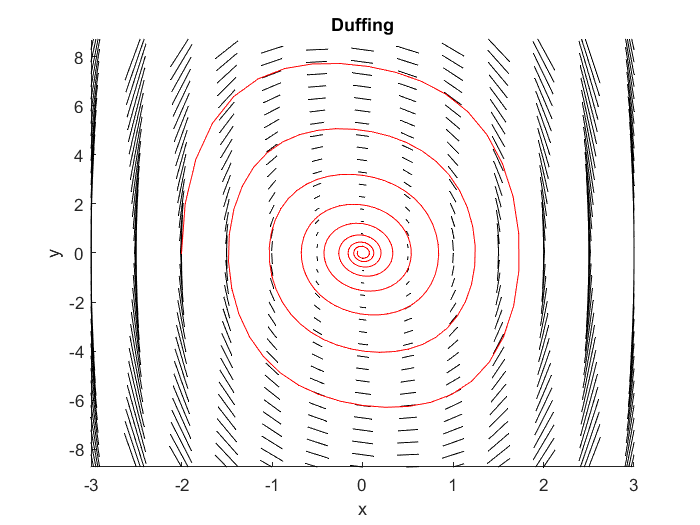

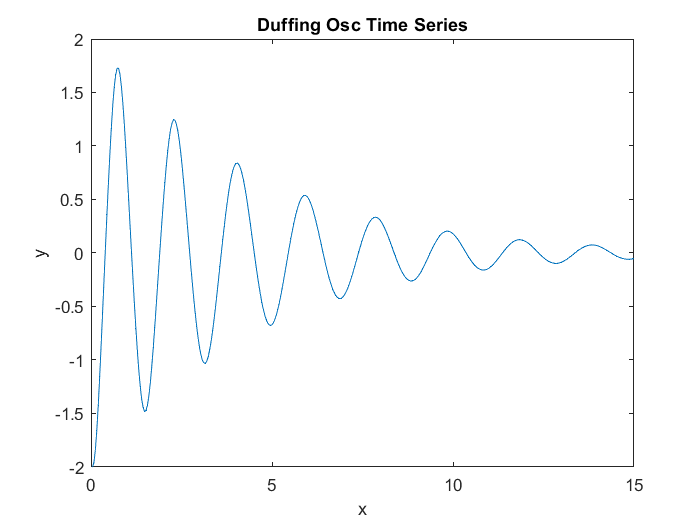

[t,x] = VanDerPol_v2(.5,.5,-1,1,2*pi,15);

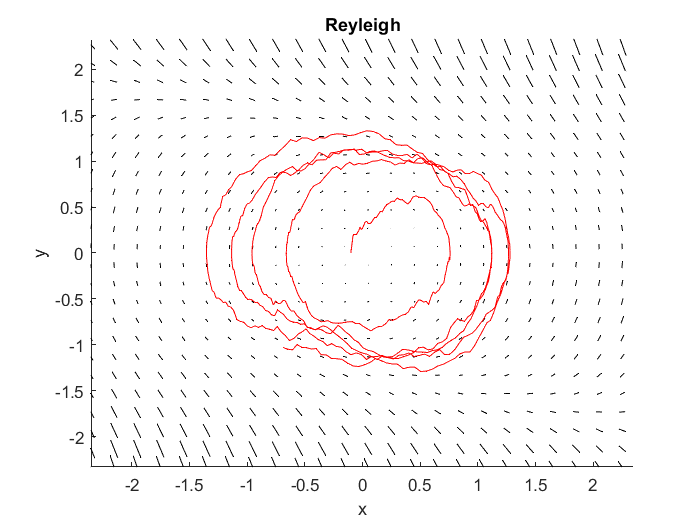


[t,x] = Rayleigh_v2(-.1,0,-1,1.3,pi,15);

% Duffing system

[t,x] = DuffingOsc(-2,0,.5,4,pi,15);

### Rayleigh oscillator with the noise term

Explore what happens to the numerical simulation as you increase the amount of noise in the system.

[t,x] = Rayleigh_Noise(-.1,0,.6,.6,30);  % first two numbers (-0.1 ,0) are the initial conditions (angle -0.1 rad, velocity 0 rad/s)

## Forced oscillators

### Damped Mass Spring System with Forcing

Simulate forced mass spring system. See [Acheson (1997) p. 57](https://books.google.com/books/about/From_Calculus_to_Chaos.html?id=o3Aq3Jt5-gEC):

Input parameters:

- b - damping

- k - stiffness (note that k^2 is the natural frequency of the system) - the function is written such that k^2 is used for numerical iteration of the ODE (line 82 in ForcedDampedMassSpring)

- beta - amplitude of the forcing function

- omega - frequency of the daming function

#### Simulate resonance phenomenon - growth of oscillation due to forcing at natural frequency (omega = 0.5 Hz, omega_f = 0.5 Hz)

b = 0; % Damping term
k = 0.5*(2*pi); % where the first number is natural frequency (0.5 Hz)

beta = 1; % amplitude of forcing
omega_f = 0.5*(2*pi); % where the first number is the forcing frequency (0.5 Hz)


processing... ... ...


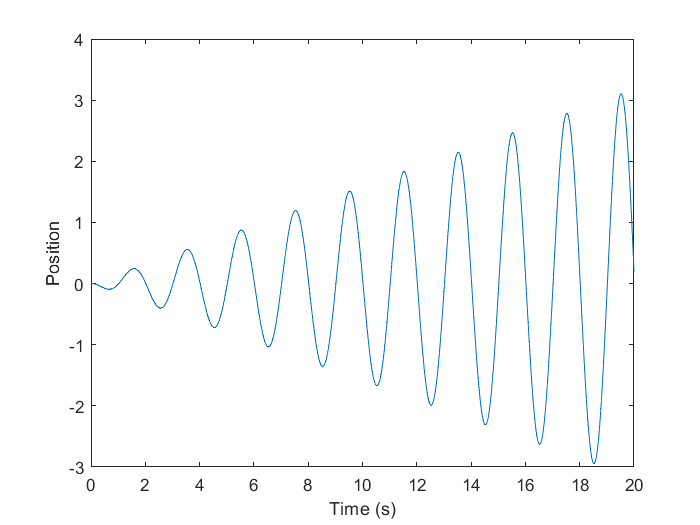

[t x] = ForcedDampedMassSpring(0,0,b,k,beta,omega_f,20,0); % first two numbers (0,0) are the initial conditions (angle 0 rad, velocity 0 rad/s)
plot(t,x(:,1))
xlabel('Time (s)')

ylabel('Position')

#### Simulate resonance phenomenon with damping - growth of oscillation due to forcing at natural frequency (omega = 0.5 Hz, omega_f = 0.5 Hz) until a limit related to the presence of damping

b = 0.5; % Damping term
k = 0.5*(2*pi); % where the first number is natural frequency (0.5 Hz)

beta = 1; % amplitude of forcing
omega_f = 0.5*(2*pi); % where the first number is the forcing frequency (0.5 Hz)

[t x] = ForcedDampedMassSpring(0,0,b,k,beta,omega_f,20,0);

processing... ... ...


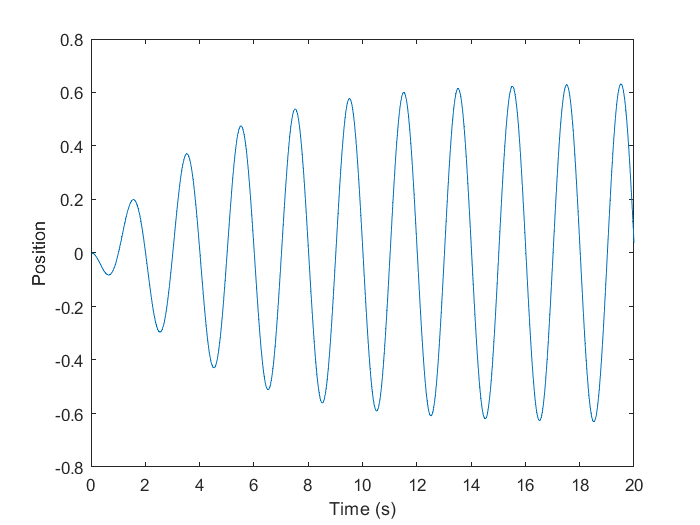

plot(t,x(:,1))
xlabel('Time (s)')
ylabel('Position')

#### Finally, simulate forcing at a frequency different from natural frequency (omega = 0.5 Hz, omega_f = 0.65 Hz). I also decreased the damping term.

b = 0.05; % Damping term
k = 0.5*(2*pi); % where the first number is natural frequency (0.5 Hz)

beta = 1; % amplitude of forcing
omega_f = .65*(2*pi); % where the first number is the forcing frequency (0.5 Hz)

[t x] = ForcedDampedMassSpring(0,0,b,k,beta,omega_f,20,0);

processing... ... ...


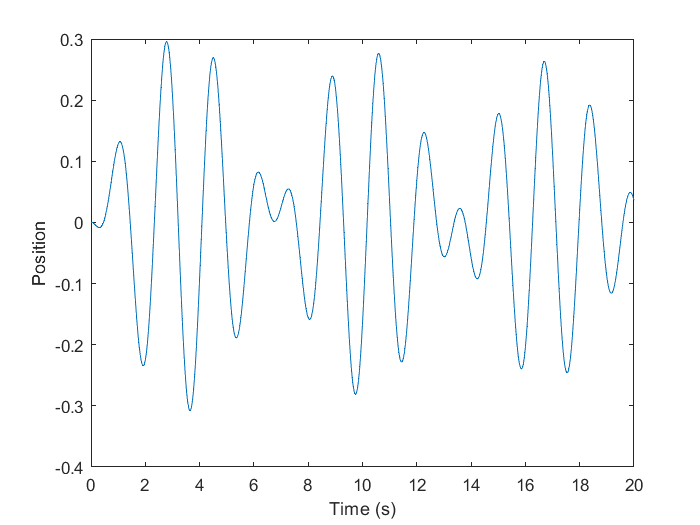

plot(t,x(:,1))
xlabel('Time (s)')
ylabel('Position')

### Simulate forced Duffing oscillator

Simulate the following system:

Input parameters:

- b - damping

- epsion - duffing term 

- k - stiffness (note that k^2 is the natural frequency of the system) - the function is written such that k^2 is used for numerical iteration of the ODE

- beta - amplitude of the forcing function

- omega - frequency of the daming function

b = 0.1; % Damping term
epsion = 10; % Duffing term amplitude
k = 0.5*(2*pi); % where the first number is natural frequency (0.5 Hz)

beta = 1; % amplitude of forcing
omega_f = 0.5*(2*pi); % where the first number is the forcing frequency (0.5 Hz)

[t x] = ForcedDuffing(0,0,b,epsion,k,beta,omega_f,60,0)

processing... ... ...


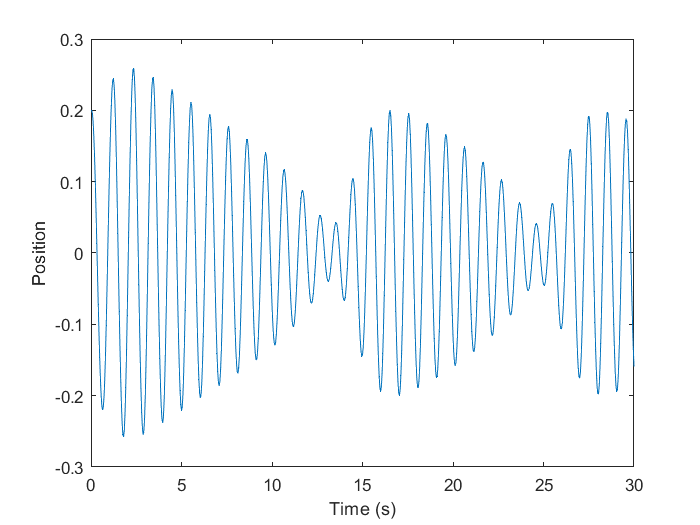

plot(t,x(:,1))
xlabel('Time (s)')
ylabel('Position')

#### Simulate Forced Rayleigh Oscillator 

Simulate the following system:

Input parameters:

- b - damping

- epsilon - Rayleigh term 

- k - stiffness (note that k^2 is the natural frequency of the system) - the function is written such that k^2 is used for numerical iteration of the ODE

- beta - amplitude of the forcing function

- omega - frequency of the daming function

b = 0.1; % Damping term
epsilon = 1; % Duffing term amplitude
k = 0.3*(2*pi); % where the first number is natural frequency (0.5 Hz)

beta = 1; % amplitude of forcing
omega_f = 0.5*(2*pi); % where the first number is the forcing frequency (0.5 Hz)

[t,x] = Forced_Rayleigh(0, k, epsilon, beta, omega_f, 30, 0); % first number 0 is the initial position of the oscillator (the rest of the initial conditins are on line 25 in the Forced_Rayeigh function).

processing... ... ...


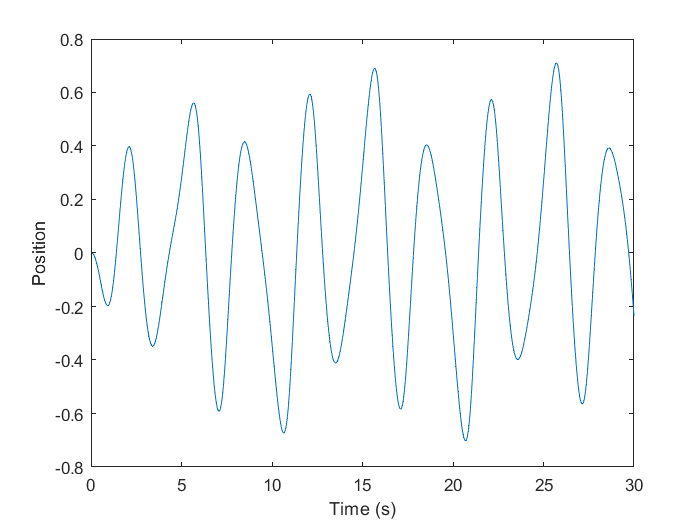


plot(t,x(:,1))
xlabel('Time (s)')
ylabel('Position')

#### Simulate coupled oscillators of the HKB model

Input:

-   Pos1 & Pos2     :-> Beta coupling constants for oscillators (e.g. 1,1 =: inphase;  1,-1 =: antiphase)    

-  b               :-> positve damping

-        beta            :-> Beta coupling constants for oscillators

-        alpha           :-> Aplha coupling constant for oscillators

-        k1 & k2         :-> Stiffness constants for oscillators

-        sigma           :-> nonlinear Escapement constants for oscillators

-        gamma           :-> nonlinear Escapement constants for oscillators

-        q               :-> the gain of Noise for oscillators

-        Rseed           :-> sets the seed on the noise generator

-        stoptime        :-> length of time for simulation

-        ssample rate    :-> Hz, e.g 100

-         plotflag        :-> do plot = 1, no plot = 0;

 %   Outputs

-         t1              :-> time array

-         y1              :-> position and velocities of oscillators,  y[Osc1_pos, Osc1_vel, Osc2_pos, Osc2_vel]

-         NOISE_FUNCS      :-> noise array used during simulation

processing... ... ...


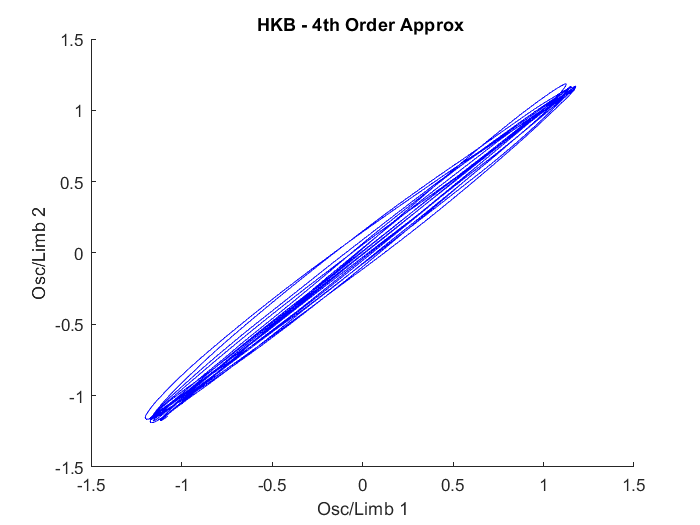

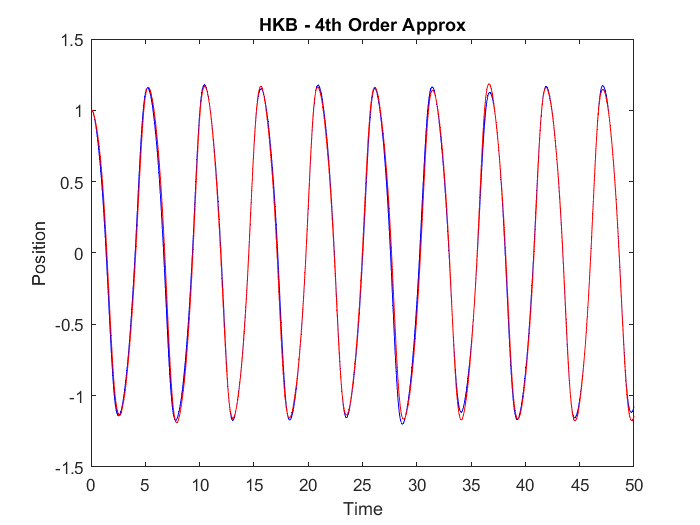

% In-phase oscilllation
[t1,y1,noise_array] = HKB_4thOrder(1,1,-1,0.2,2,1.2,1.2,0.2,-0.2,.1, 50, 20, 1);

% anti-phase oscilllation
[t1,y1,noise_array] = HKB_4thOrder(1,-1,-1,0.2,2,1.2,1.2,0.2,-0.2,.1, 50, 20, 1);

% Transition from anti-phase to in-phase oscilllation
[t1,y1,noise_array] = HKB_4thOrder(1,-1,-1,0.2,2,1.2,1.2,0.2,-0.2,.1, 50, 20, 1);